# Import data from text file

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 7);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["t", "lambda", "s", "f", "x", "y", "z"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
blk = readtable("block.csv", opts);
clear opts

Statistics:

max(blk.t)

ans = 10.2110

max(blk.f)

ans = 16.6657

## Lambda and feedrate

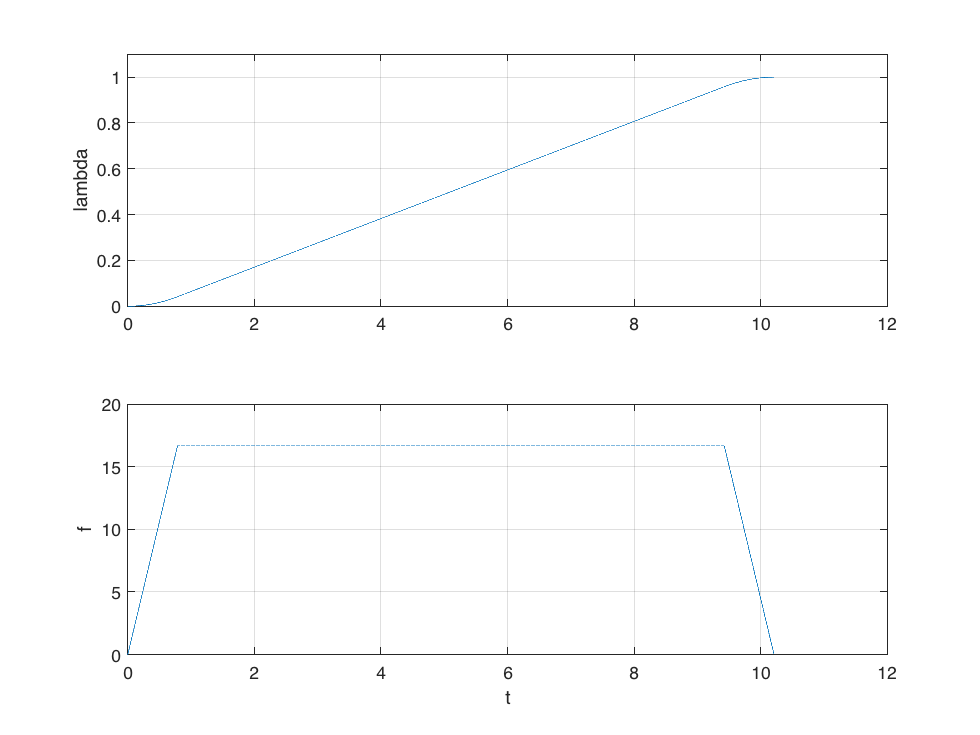

figure;
subplot(2,1,1);
plot(blk.t, blk.lambda)
ylim([0, 1.1]);
ylabel lambda;
grid on
subplot(2,1,2);
plot(blk.t, blk.f)
ylabel f
xlabel t
grid on

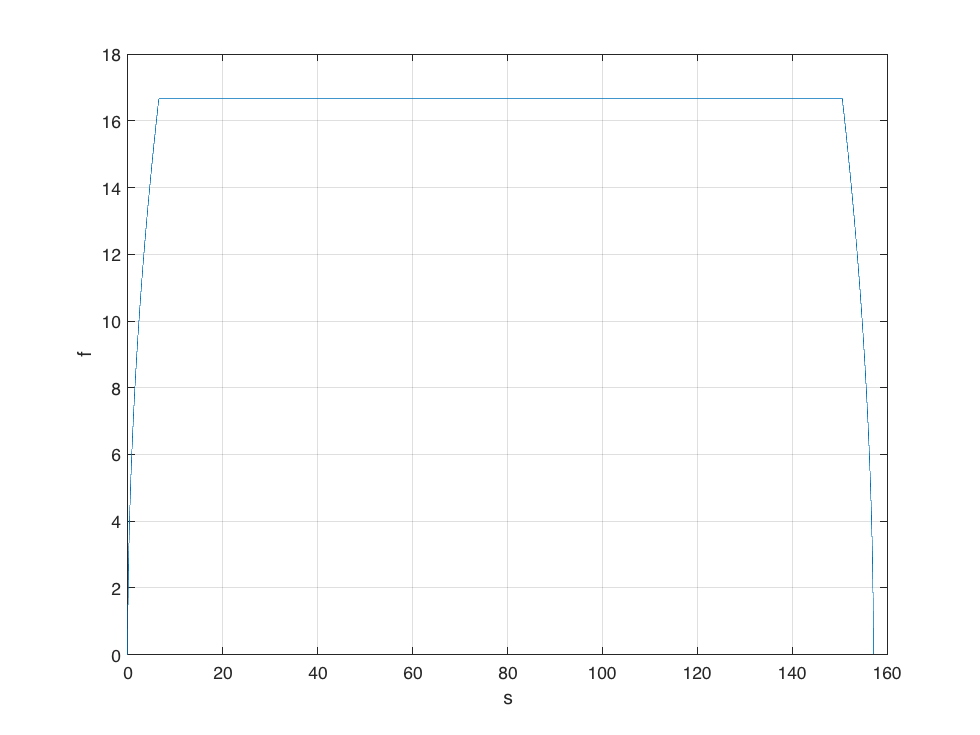

figure
plot(blk.s, blk.f)
ylabel f;
xlabel s;
grid on

## Coordinates

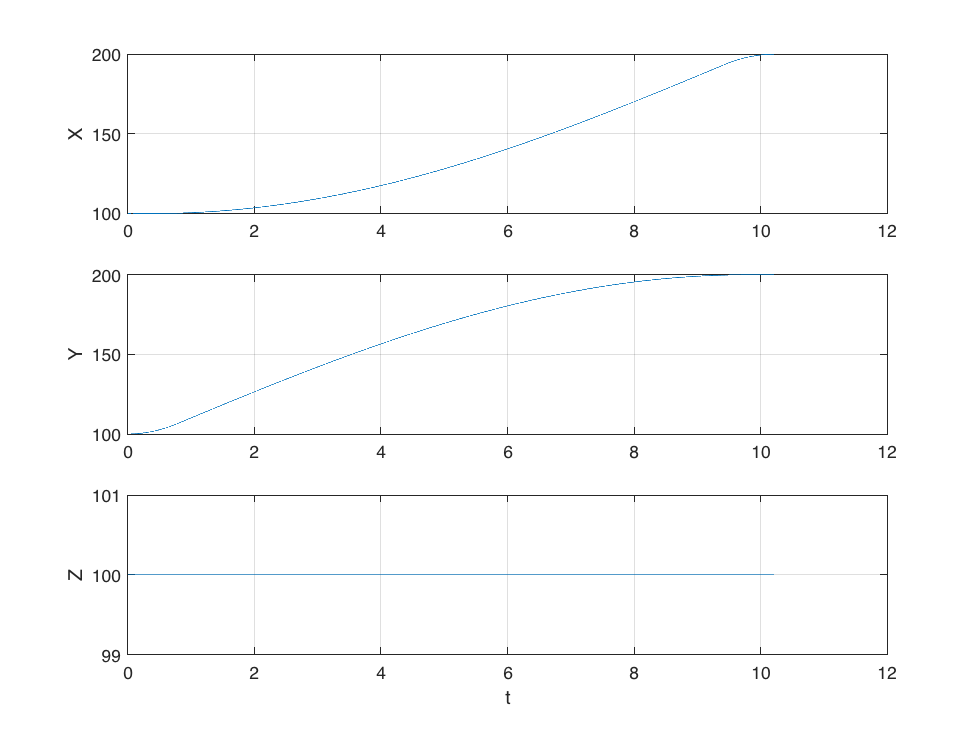

figure;
subplot(3,1,1);
plot(blk.t, blk.x)
grid on
ylabel X
subplot(3,1,2);
plot(blk.t, blk.y);
grid on
ylabel Y
subplot(3,1,3);
plot(blk.t, blk.z);
grid on
ylabel Z
xlabel t

## Trajectory

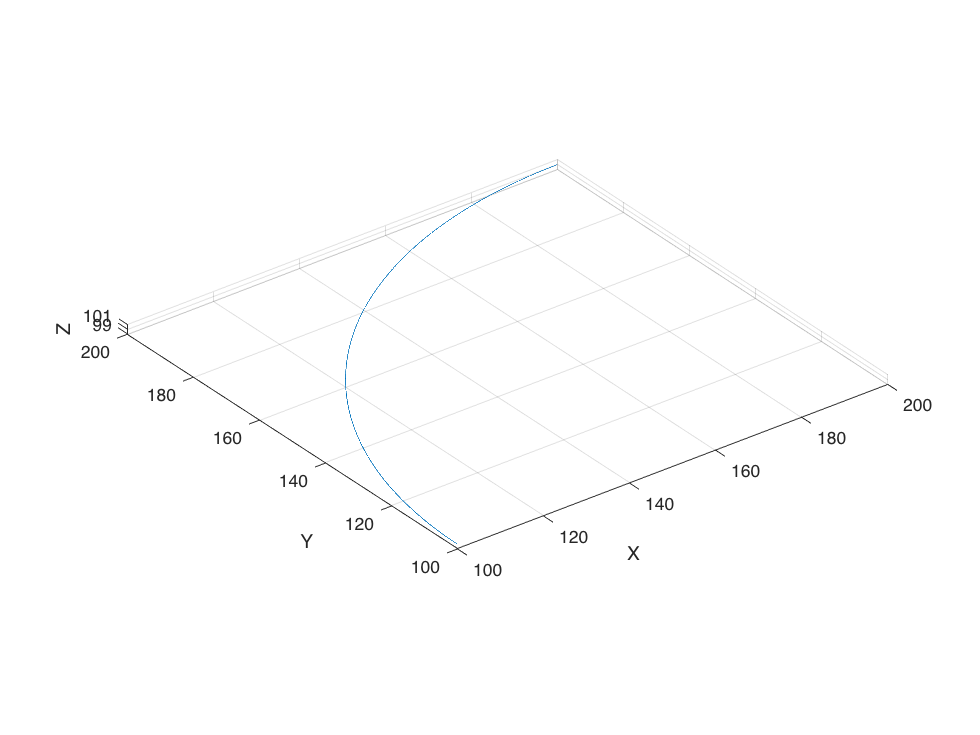

figure
plot3(blk.x, blk.y, blk.z)
axis equal
grid on
xlabel X
ylabel Y
zlabel Z